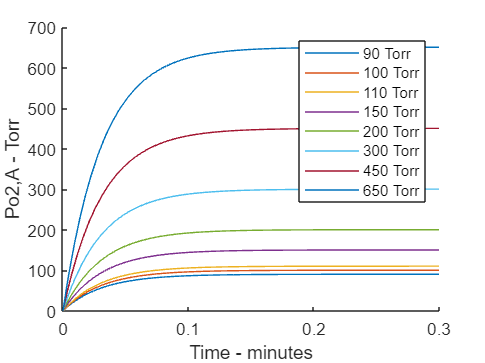

Vc = 70;  %in ml
O = 2.33;  %min^-1
Dm = 40; %in ml/min

Dl = (O*Vc*Dm)/(O*Vc+Dm);

tspan = [0,0.3];
Po = 0;

hold on
for PA = [90 100 110 150 200 300 450 650]
    f = @(t,Pa) Dl*(PA - Pa);
    [x,y] = ode45(f,tspan,Po);
    plot(x,y)
end
xlabel('Time - minutes');
ylabel('Po2,A - Torr');
legend('90 Torr', '100 Torr', '110 Torr', '150 Torr', '200 Torr', '300 Torr', '450 Torr', '650 Torr');
hold off